cd imgs/pasupathy-wg-f-4-ori/
img = imread('pasu_50_ori_07_wg_f.jpg')

img = 343×344 uint8 矩阵
   184   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128
   184   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128
   184   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128   128
   184   128   128   128   128   128   128   128   128   128   128   128  

img_bw = img(:,:,1) < 185;
B=bwboundaries(img_bw,8)%'noholes'

B = 2×1 cell 数组
    {1371×2 double}
    { 989×2 double}


cd ../../

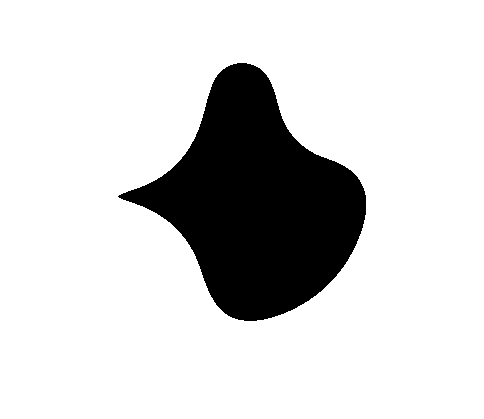

imshow(img_bw)

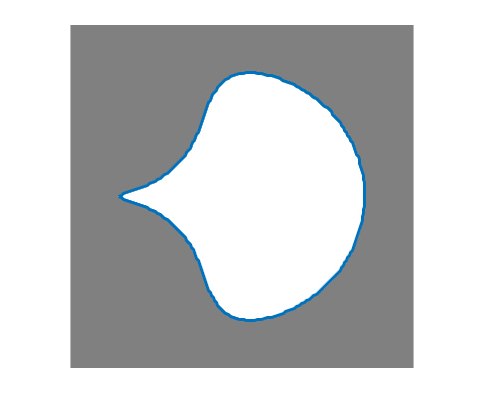

figure
imshow(img)
hold on 
for Bdr_i=2%length(B)
plot(B{Bdr_i}(1:4:end,2),B{Bdr_i}(1:4:end,1),"LineWidth",3)
end

curv_pnts = B{2};

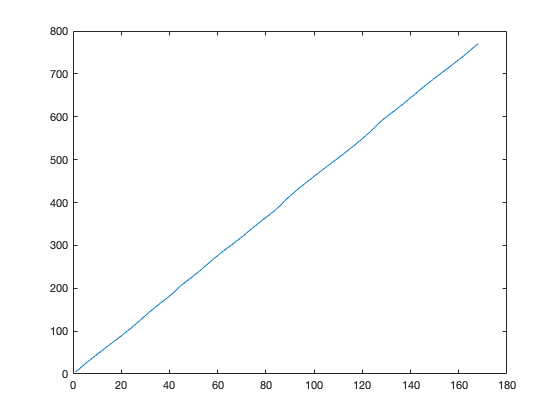

stride = 6;
curv_ds = sqrt(sum((curv_pnts(1:stride:end-stride,:) - curv_pnts(stride+1:stride:end,:)).^2,2));
curv_s = cumsum(curv_ds);
figure
plot(curv_s)

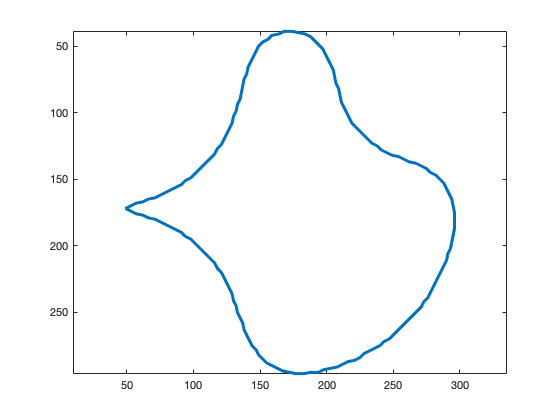

figure;
plot(B{Bdr_i}(1:stride:end,2),B{Bdr_i}(1:stride:end,1),"LineWidth",3)
axis equal;set(gca,'YDir','reverse')

% curv_ds is constantly one. 

Xcoor = B{2}(1:stride:end, 2);
Ycoor = B{2}(1:stride:end, 1);
Zcoor = Xcoor + j * Ycoor;
N = length(Xcoor);
Ucoef = fft(Zcoor);
UAmp = abs(Ucoef);
UAng = angle(Ucoef);

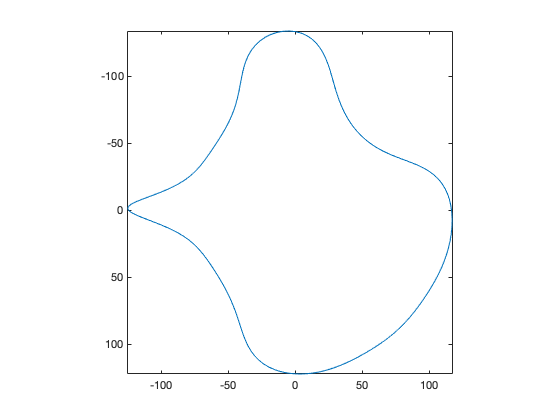

comp_n = 10;
FFTidx = [2:comp_n + 1,N-comp_n+1:N];
%1/length(UAmp)
theta = [0:1/N:1];%[0:length(UAmp)-1]/length(UAmp);%[0:0.001:1]%
freq = [0:N-1]';
Xfit = sum(UAmp(FFTidx) .* cos(2*pi*freq(FFTidx) * theta + UAng(FFTidx)), 1)/N;
Yfit = sum(UAmp(FFTidx) .* sin(2*pi*freq(FFTidx) * theta + UAng(FFTidx)), 1)/N;
figure
plot(Xfit,Yfit)
axis image equal
set(gca,"YDir","reverse")

pasu_path = "imgs/pasupathy-wg-f-4-ori/";
imlist = dir(fullfile(pasu_path,"*.jpg"))

imlist = 包含以下字段的 186×1 struct 数组:
    name
    folder
    date
    bytes
    isdir
    datenum


imlist = dir(fullfile(pasu_path,"*.jpg"))

imlist = 包含以下字段的 186×1 struct 数组:
    name
    folder
    date
    bytes
    isdir
    datenum


imlist = struct2cell(imlist);

ans = 1×1 cell 数组
    {[0]}


imgnms = cellstr(imlist(1,:));

stride = 4

stride = 4

Bd_col = {};
FFT_col = {};
for imgi = 1:length(imgnms)
    img = imread(fullfile(pasu_path, imgnms{imgi}));
    img_bw = img(:,:,1) < 185;
    B=bwboundaries(img_bw,8);
    Xcoor = B{2}(1:stride:end, 2);
    Ycoor = B{2}(1:stride:end, 1);
    Zcoor = Xcoor + j * Ycoor;
    N = length(Xcoor);
    Ucoef = fft(Zcoor);
    Bd_col{imgi} = B{2};
    FFT_col{imgi} = Ucoef;
end

comp_n = 10;
FFTidx = [2:comp_n + 1,N-comp_n+1:N];
%1/length(UAmp)
theta = [0:1/N:1];%[0:length(UAmp)-1]/length(UAmp);%[0:0.001:1]%
freq = [0:N-1]';
Xfit = sum(UAmp(FFTidx) .* cos(2*pi*freq(FFTidx) * theta + UAng(FFTidx)), 1)/N;
Yfit = sum(UAmp(FFTidx) .* sin(2*pi*freq(FFTidx) * theta + UAng(FFTidx)), 1)/N;
figure
plot(Xfit,Yfit)
axis image equal
set(gca,"YDir","reverse")